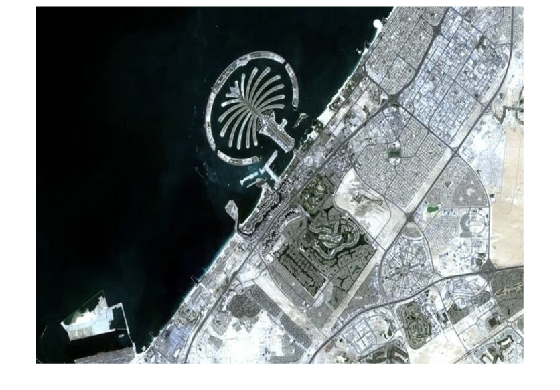

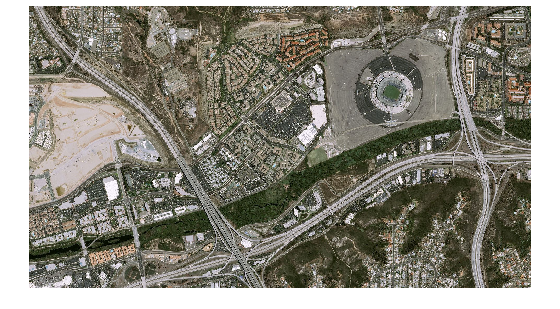

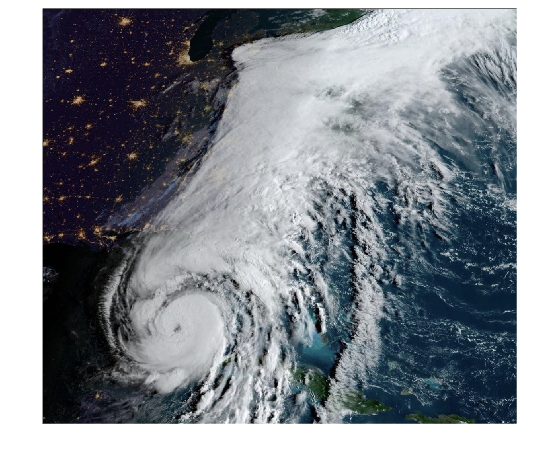

clear all 
close all
clc

imagefiles = dir("Test Images/Original/*");      
nfiles = length(imagefiles);    % Number of files found

for ii=4:nfiles
   currentfilename = imagefiles(ii).name;
   currentimage = imread(currentfilename);
   images{ii - 3} = currentimage;
   [~,imageNames{ii - 3},~] = fileparts(currentfilename);
   figure()
   imshow(images{ii - 3});
end


snippedDir = dir("Test Images/Snipped/"); 
rmdir(snippedDir(1).folder,'s')

mkdir(snippedDir(1).folder)

numSnips = 20;
snipDims = [300, 300];
for i=1:length(images)
    mkdir(strcat(snippedDir(1).folder, '/', imageNames{i}));
    for j = 1:numSnips
        image = images{i};
        sz = size(image);
        windowMax = [randi([snipDims(1), sz(1)]), randi([snipDims(2), sz(2)])];
        subimage = image(windowMax(1)-snipDims(1):windowMax(1), windowMax(2)-snipDims(2):windowMax(2), :);
        imwrite(subimage,strcat(snippedDir(1).folder, '/', imageNames{i}, '/', imageNames{i}, string(j), '.jpg'));
    end
end